# **Procesamiento de Imagenes Digitales**

# **Taller 10**

**Blurred Image**

Cargue el archivo `“Datos.mat”`, y visualice en la `figura 1` (asigne un título) la imagen `Blurred`, la cual esta contenida en el archivo como un arreglo bidimensional.

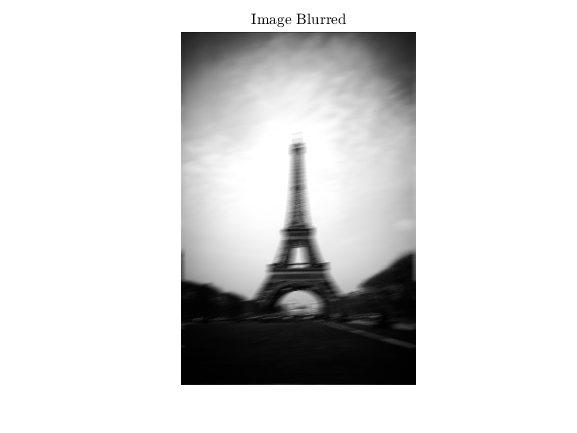

load('Datos.mat');  
figure(1);
imshow(Blurred,[]);title('Image Blurred','interpreter','latex');

El efecto Blur de la imagen, en este caso, se debe a un movimiento lineal involuntario de la cámara. Simule un PSF para esta imagen con un kernel de `“movimiento”` de 21 unidades de `longitud` y 11 unidades de `rotación`. Puede utilizar la función `fspecial`. 

len = 21; theta = 11;
PSF = fspecial('motion', len, theta);

Aplique el filtro *Wiener-Helstrom*, con la información que tiene hasta este momento, y visualice en la `figura 2` (asigne un título). Puede utilizar la función `deconvwnr`. 

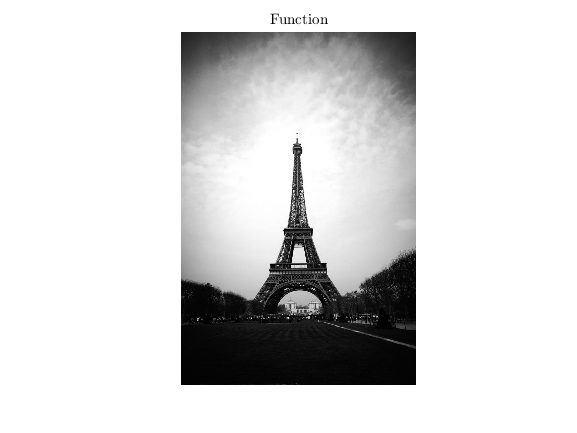

F = deconvwnr(Blurred,PSF);
figure(2);
imshow(F,[]);title('Function','Interpreter','latex');

**Blurred and Noisy Image**

Visualice, en la `figura 3`, la imagen con efecto Blur y ruido añadido (asigne un título).

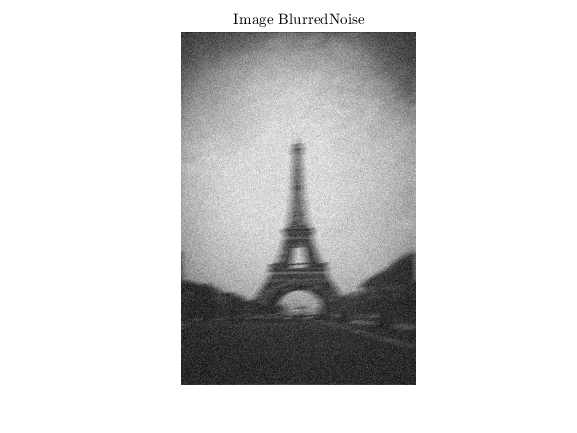

figure(3);
imshow(BlurredNoisy,[]);title('Image BlurredNoise','interpreter','latex');

Calcule el escalar de la relación señal-ruido $(NSR)$, para lo cual puede generar una matriz de ruido aleatorio $n$ con $-1<n<1$, amplificada $15$ veces (visualice la variable $NSR$ en pantalla).

N = 15.*randn(size(BlurredNoisy)-1);
Wf = abs(fft2(F)).^2;
Wn = abs(fft2(N)).^2;
NSR = sum(Wn(:))/sum(Wf(:));

Aplique el filtro *Wiener-Helstrom*, a la imagen con efecto Blur y ruido añadido, utilizando información que tiene hasta este momento, y visualice en la `figura 4` (asigne un título).

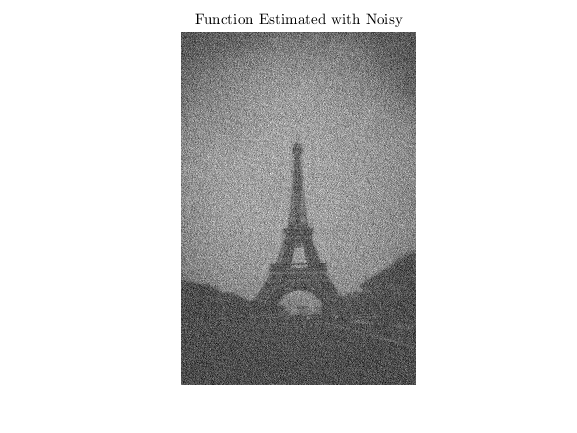

Fn = deconvwnr(BlurredNoisy, PSF, NSR);
figure(4);
imshow(Fn,[]);title('Function Estimated with Noisy','interpreter','latex');

Lleve al dominio espacial la parte *real* de $W_{N}$ y $W_{F}$ (Matrices de Correlación), y filtre la imagen con la opción pendiente del filtro *Wiener-Helstrom *disponible en la función `deconvwnr`. 

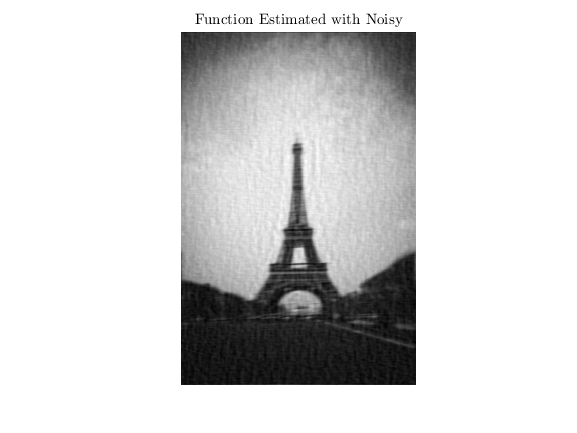

Wfs = ifft2(real(Wf));
Wns = ifft2(real(Wn));
Fns = deconvwnr(BlurredNoisy, PSF, Wns, Wfs);
figure(5);
imshow(Fns,[]);title('Function Estimated with Noisy','Interpreter','latex');